# **Tarea filtro pasabajas**

**Gallegos Ruiz Diana Abigail**

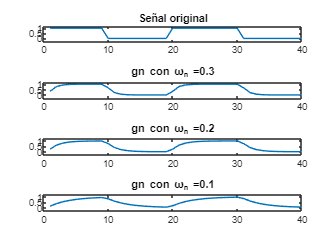

clc
close all;

wn=[0.3,0.2,0.1];

for i=1:40
    if i <10 ||  (i>=20 && i<=30)
        fn(i)=1;
    else
        fn(i)=0;
    end
end

figure(1)
tiledlayout(4,1);


nexttile
plot(fn)
title('Señal original')
ylim([-0.3 , 1.2])

for i=1:3
    [N,D] = butter(1,wn(i),'low');
    gn=filter(N,D,fn);
    nexttile
    plot(gn)
    title(strcat( 'gn con \omega_n = ', num2str(wn(i)) ))
    ylim([-0.3 , 1.2])
end